# Design Cooling System

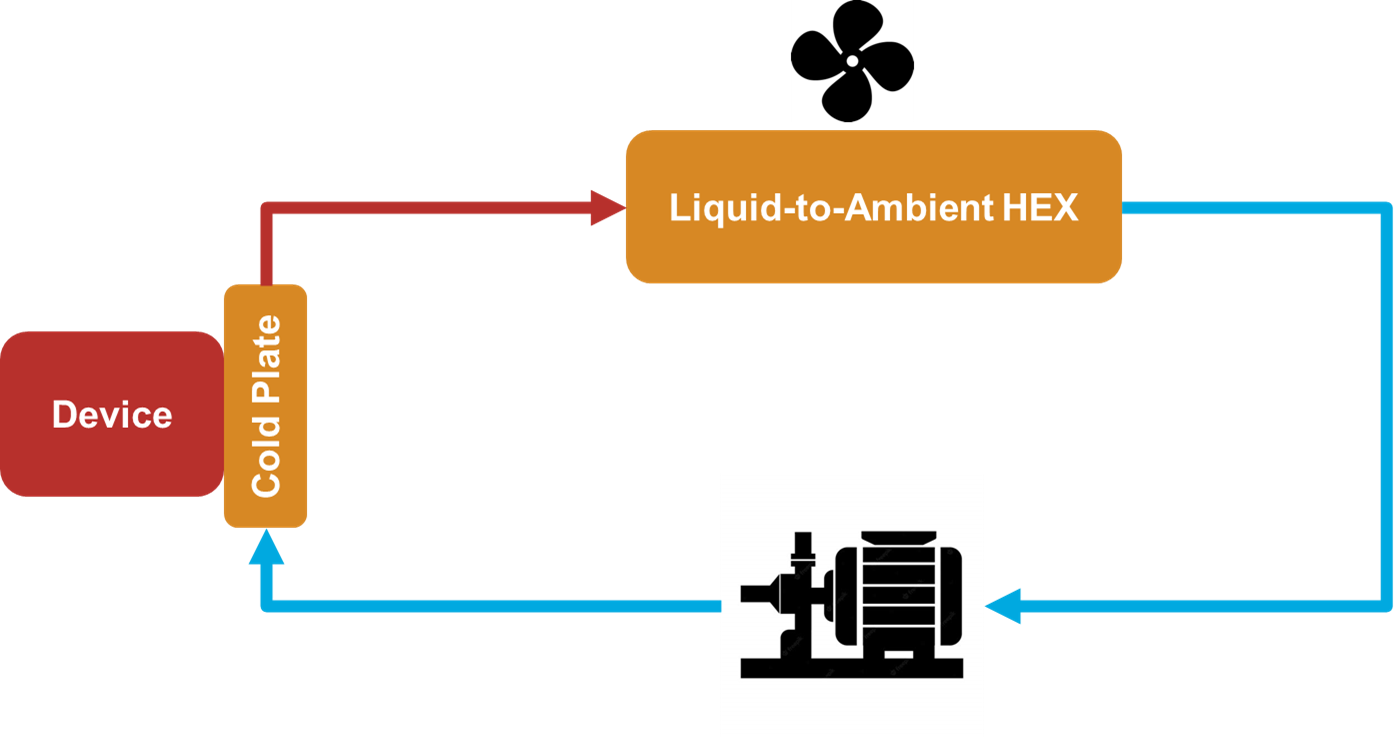

### Requirements for X-Ray Tube Cooling

- Remove up to 2 kW 

- Allowed coolant temperature rise 5°C

- Temperature set point: 25°C

- Device temperature should not exceed 50°C

- Working fluid: Water

- Temperature stability +/- n°C

- Operating conditions: (at what temperatures is the thing operated and “where” is it) 15°C-40°C

- Tout must ot excess 30°C 

Steady state calculations

Final surface temperature of cooled device


$$T_{\textrm{surface}} =Q_{\textrm{Diss}} *R_{\textrm{CP}} \;+T_{\textrm{cp},\textrm{out}}$$


Cold plate heat transfer


$$Q_{\textrm{Diss}} =\left(T_{\textrm{cp},\textrm{out}} -T_{\textrm{cp},\textrm{in}} \right)*{\dot{m} }_{\textrm{water}} *c_{p,\textrm{water}}$$


Heat transfer in ambient air heat exchanger


$$Q_{\mathrm{Diss}} =\varepsilon *C_{\min } *\left(T_{\mathrm{cp},\mathrm{out}} -T_{\mathrm{Air}} \right)$$


with 


$$C_{\textrm{water}} =\;$$

$${\dot{m} }_{\textrm{water}} *c_{p,\textrm{water}}$$



$$C_{\textrm{air}} =\;$$

$${\dot{m} }_{\textrm{air}} *c_{p,\textrm{air}}$$



$$C_{\min } =\min \left(C_{\textrm{water}} ,C_{\textrm{air}} \right)$$


#### Requirements and operating conditions

QDot            = 2000;         % (W) Heat load
deltaTCoolant   = 5;            % (°C) Maximum temperature rise allowed
TCoolantIn      = 25;           % (°C) Assumed coolant inlet temperature
TCoolantOutMax  = 30;           % (°C) Maximum coolant outlet temperature
TSurfaceMax     = 50;           % (°C) Maximum device temperature
TAmbient        = 20;           % (°C) Ambient temperature

#### Water properties at 25°C 

cpCoolant       = 4181;         % (J/(kg*K)) heat cpacity
rhoCoolant      = 997;          % (kg/m^3) density
muCoolant       = 0.00105;      % Pa·s
kCoolant        = 0.6;          % W/(m*K)
PrCoolant       = 6.13          % (1) Prandtl number

PrCoolant = 6.1300

#### Air porperties at 20°C

cpAir           = 1006;         % (J/(kg*K)) heat cpacity
rhoAir          = 1.204;        % (kg/m^3) density
kinViscAir      = 15e-6;        % (m^2/s) kinematic viscosity
PrAir           = 0.71;         % (1) Prandtly number
kAir            = 0.026;        % W/(m*K) 

#### Cold Plate

#### Determine required flow rate at operating conditions

mDot    = QDot/(cpCoolant*deltaTCoolant); % (kg/s) Mass flow rate
VDot    = mDot/rhoCoolant;                % (m^3/s) Volumetric flow rate
VDotLPM = mDot/rhoCoolant*1000*60;        % (l/min) Volumetric flow rate

Test steady state cold plate outlet temperature for different flow rates at constant heat

VDotLPMVec = 2:8;                                      % l/min
mDotVec    = VDotLPMVec*0.001/60*rhoCoolant;            % kg/s
TCoolantOutVec  = QDot./(mDotVec*cpCoolant)+TCoolantIn;

plot(VDotLPMVec,TCoolantOutVec)
xlabel('Flow rate [l/min]')
ylabel('T_{cp,out}, [°C]');
hold on

Verify in Simscape model 

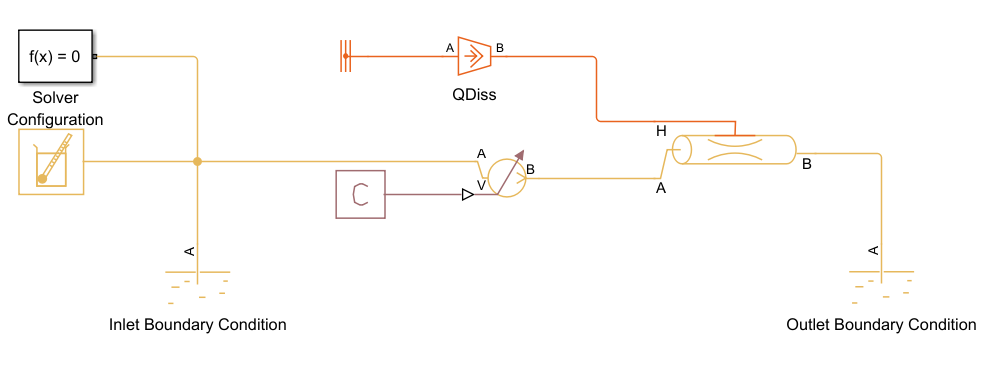

for i = numel(VDotLPMVec):-1:1
    simInp(i) = Simulink.SimulationInput('example_TCoolantOut_SteadyState');
    simInp(i) = simInp(i).setVariable('flowRate',VDotLPMVec(i));
end

simOut = sim(simInp, UseFastRestart="on");

[07-Aug-2025 14:42:54] Running simulations...
[07-Aug-2025 14:43:32] Completed 1 of 7 simulation runs
[07-Aug-2025 14:43:34] Completed 2 of 7 simulation runs
[07-Aug-2025 14:43:35] Completed 3 of 7 simulation runs
[07-Aug-2025 14:43:36] Completed 4 of 7 simulation runs
[07-Aug-2025 14:43:39] Completed 5 of 7 simulation runs
[07-Aug-2025 14:43:40] Completed 6 of 7 simulation runs
[07-Aug-2025 14:43:40] Completed 7 of 7 simulation runs


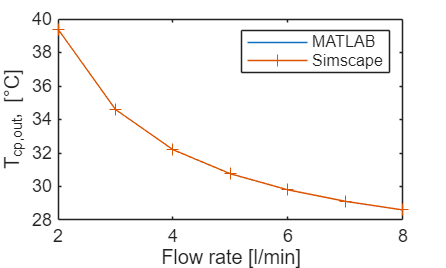


TCoolantOutVecSim = zeros(size(simInp));

for i = 1:numel(VDotLPMVec)
    TCoolantOutTemp = simOut(i).simlog.Pipe_TL.B.T.series.values('degC');
    TCoolantOutVecSim(i) = TCoolantOutTemp(end);
end
clear TCoolantOutTemp simInp

plot(VDotLPMVec,TCoolantOutVecSim,'-+')
xlabel('Flow rate [l/min]')
ylabel('T_{cp,out}, [°C]');
legend('MATLAB','Simscape')
hold off

#### Cold plate resistance for maximum surface temperature at maximum coolant outlet temperature

Rcp = (TSurfaceMax - TCoolantOutMax)/QDot;   % K/W

Test resistance for different flow rates/outlet temperature 

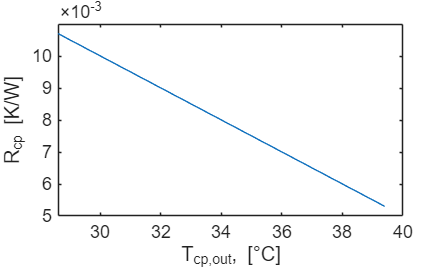

VDotLPMVec      = 2:8;     % (lpm)
mDotVec         = VDotLPMVec*0.001/60*rhoCoolant;    
TCoolantOutVec  = QDot./(mDotVec*cpCoolant)+TCoolantIn;

RcpVec = (TSurfaceMax - TCoolantOutVec)/QDot;   % K/W

figure
plot(TCoolantOutVec,RcpVec)
xlabel('T_{cp,out}, [°C]');
ylabel('R_{cp} [K/W]')

Verify in Simscape model

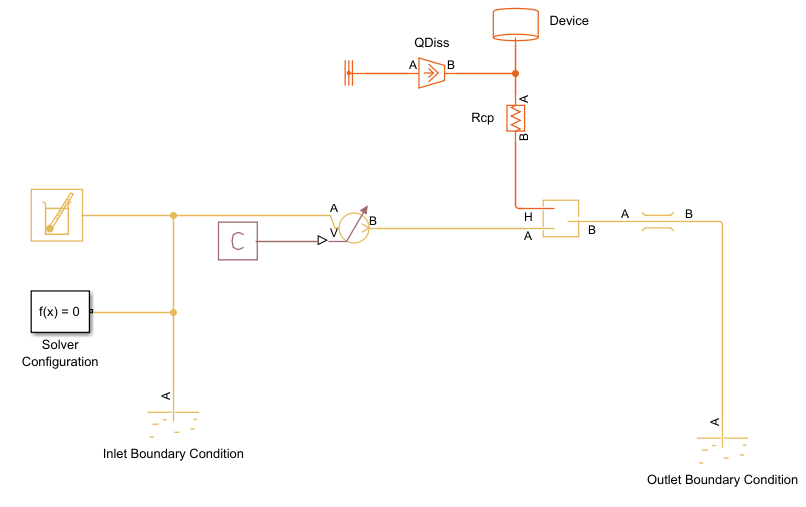

for i = numel(VDotLPMVec):-1:1
    simInp(i) = Simulink.SimulationInput('example_Rcp_Chamber_SteadyState');
    simInp(i) = simInp(i).setVariable('Rcp',RcpVec(i));
    simInp(i) = simInp(i).setVariable('flowRate',VDotLPMVec(i));
end

simOut = sim(simInp);

[07-Aug-2025 14:43:45] Running simulations...
[07-Aug-2025 14:43:55] Completed 1 of 7 simulation runs
[07-Aug-2025 14:43:59] Completed 2 of 7 simulation runs
[07-Aug-2025 14:44:02] Completed 3 of 7 simulation runs
[07-Aug-2025 14:44:05] Completed 4 of 7 simulation runs
[07-Aug-2025 14:44:07] Completed 5 of 7 simulation runs
[07-Aug-2025 14:44:09] Completed 6 of 7 simulation runs
[07-Aug-2025 14:44:11] Completed 7 of 7 simulation runs


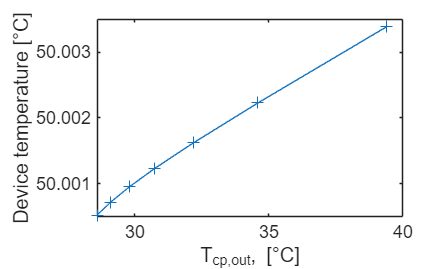


TDeviceOutSim = zeros(size(VDotLPMVec));

for i = 1:numel(VDotLPMVec)
    TDeviceTemp = simOut(i).simlog.Device.M.T.series.values('degC');
    TDeviceOutSim(i) = TDeviceTemp(end);
end
clear TDeviceTemp  simInp
figure
plot(TCoolantOutVec,TDeviceOutSim,'-+')
xlabel('T_{cp,out}, [°C]');
ylabel('Device temperature [°C]')

**Size cold plate**

% Rcp goal = 0.01
% Example: Detector Cold Plate Spec Summary
% Material: Aluminum 167 W/m/K
% Size: 80 × 200 × 6 mm  
% Channels: Serpentine, 3.5 mm wide × 3 mm deep
% Channel length
% Wall thickness between channels >1mm
% Material thickness under channel floor >2mm

% Cold plate external dimensions
% Length 200-400 mm
% Width 100-300 mm
% Thickness 10-25 mm
% Surface area cold plate to X-Ray Tube
% Tube Diameter 50-120 mm
% Channel gemoetry
% Channel width 1-5 mm
% Channel depth 2-5 mm
% Channel pitch 2-10 mm
% Wall thickness 1-2 mmm
% Serpentine channels, channel length: 

cpL     = 300*0+250; % mm
cpW     = 200*0+150; % mm
deviceD = 75; % mm
cpDeviceSurfaceArea = pi*(deviceD/1000/2)^2; % m^2
cpK         = 167; % W/(mÜK)
cpThickness = 7; % mm

channelWidth    = 5; % mm
channelHeight   = 4;   % mm
channelPitch    = 10; % mm
effFlowLength   = 220; % mm
numPasses       = 15; % number of channel passes 
numChannels     = 1;
channelLength   = numPasses*effFlowLength/1000*numChannels; % m 
channelArea     = channelHeight*channelWidth; % mm^2
channelDh       = channelWidth*channelHeight/(channelHeight+channelWidth); % mm
channelRoughness = 15e-6; % m


Test Rcp for given cold plate for different flow rates in Simscape model 

VDotLPMVec = 2:8;                    % l/min

for i = numel(VDotLPMVec):-1:1
    simInp(i) = Simulink.SimulationInput('example_ColdPlate_SteadyState');
    simInp(i) = simInp(i).setVariable('flowRate',VDotLPMVec(i));
end

simOut = sim(simInp);

[07-Aug-2025 14:44:16] Running simulations...
[07-Aug-2025 14:44:22] Completed 1 of 7 simulation runs
[07-Aug-2025 14:44:24] Completed 2 of 7 simulation runs
[07-Aug-2025 14:44:26] Completed 3 of 7 simulation runs
[07-Aug-2025 14:44:28] Completed 4 of 7 simulation runs
[07-Aug-2025 14:44:30] Completed 5 of 7 simulation runs
[07-Aug-2025 14:44:33] Completed 6 of 7 simulation runs
[07-Aug-2025 14:44:35] Completed 7 of 7 simulation runs


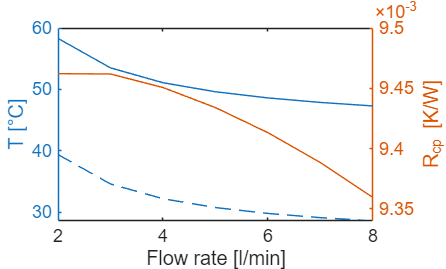


TDeviceOutSim  = zeros(size(VDotLPMVec));
TCoolantOutSim = zeros(size(VDotLPMVec));

for i = 1:numel(VDotLPMVec)
    TDeviceTemp = simOut(i).simlog.Device.M.T.series.values('degC');
    TDeviceOutSim(i) = TDeviceTemp(end);
    TCoolantOutTemp = simOut(i).simlog.Pipe_TL.B.T.series.values('degC');
    TCoolantOutSim(i) = TCoolantOutTemp(end);    
end

clear TDeviceTemp  TCoolantOutTemp simInp

RcpSim = (TDeviceOutSim-TCoolantOutSim)/QDot;

figure
yyaxis left
plot(VDotLPMVec,TDeviceOutSim,VDotLPMVec,TCoolantOutSim);
ylabel('T [°C]')

yyaxis right
plot(VDotLPMVec, RcpSim);
ylabel('R_{cp} [K/W]')

xlabel('Flow rate [l/min]')
hold off

#### Determine pressure drop

% Reynolds number
velPipe         = VDot/(channelArea*1e-6);           % (m/s) Flow velocity
Re              = rhoCoolant*velPipe*(channelDh/1000)/muCoolant; % Reynolds number

% Darcy friction factor 
if Re < 2300
    f = 64 / Re;     % Laminar flow
else
    
    f = 1 / (-1.8 * log10(6.9/Re + (channelRoughness/(channelDh/1000)/3.7)^1.11))^2; % Turbulent flow - Haaland correlation
end
% Pressure drop (not accounting for temperature differences)
deltaPCP = f * (channelLength/(channelDh/1000)) * 0.5 * rhoCoolant * velPipe^2; % (Pa)

Test pressure drop for different flow rates 

VDotLPMVec = 2:8;                    % l/min
velPipeVec = VDotLPMVec*0.001/60/(channelArea*1e-6);   % (m/s) Flow velocity
ReVec      = rhoCoolant*velPipeVec*(channelDh/1000)/muCoolant;     % Reynolds number

fVec = zeros(size(VDotLPMVec));

% Darcy friction factor 
fVec(ReVec<2000) = 64./ReVec(ReVec<2000);
fVec(ReVec>=2000) = 1 ./ ...
    (-1.8 * log10(6.9./ReVec(ReVec>=2000) + (channelRoughness/(channelDh/1000)/3.7)^1.11)).^2; 

% Pressure drop
deltaPPipeVec = fVec*(channelLength/(channelDh/1000))*0.5*rhoCoolant.*velPipeVec.^2; % (Pa)

figure
plot(VDotLPMVec,deltaPPipeVec/1e6)
xlabel('Flow rate [l/min]')
ylabel('\Delta P, [MPa]');
hold on

Test in Simscape model 

for i = numel(VDotLPMVec):-1:1
    simInp(i) = Simulink.SimulationInput('example_deltaP_SteadyState');
    simInp(i) = simInp(i).setVariable('flowRate',VDotLPMVec(i));
end

simOut = sim(simInp, UseFastRestart="on");

[07-Aug-2025 14:44:41] Running simulations...
[07-Aug-2025 14:44:45] Completed 1 of 7 simulation runs
[07-Aug-2025 14:44:45] Completed 2 of 7 simulation runs
[07-Aug-2025 14:44:45] Completed 3 of 7 simulation runs
[07-Aug-2025 14:44:46] Completed 4 of 7 simulation runs
[07-Aug-2025 14:44:46] Completed 5 of 7 simulation runs
[07-Aug-2025 14:44:46] Completed 6 of 7 simulation runs
[07-Aug-2025 14:44:46] Completed 7 of 7 simulation runs


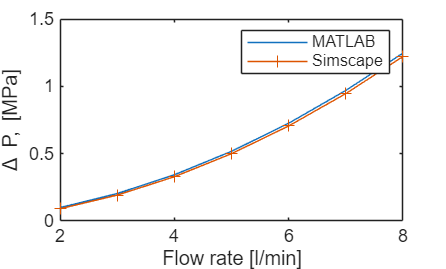


deltaPPipeVecSim = zeros(size(simInp));

for i = 1:numel(VDotLPMVec)
    pATemp = simOut(i).simlog.Pipe_TL.A.p.series.values('Pa');
    pBTemp = simOut(i).simlog.Pipe_TL.B.p.series.values('Pa');
    deltaPPipeVecSim(i) = pATemp(end)-pBTemp(end);
end
clear pATemp pBTemp simInp

plot(VDotLPMVec,deltaPPipeVecSim/1e6,'-+')
xlabel('Flow rate [l/min]')
ylabel('\Delta P, [MPa]');
legend('MATLAB','Simscape')
hold off

#### Radiator

TAirOut    = 28    % (°C) Assumed air outlet temperature

TAirOut = 28


VDotAir    = 0.15; % (m^3/s) Assumed air flow rate
mDotAir    = VDotAir*rhoAir; % kg/s 
hAir       = 100; % W/(m^2*K) Assumed heat transfer coefficient air side

% LMTD
deltaT1 = TCoolantOutMax - TAirOut;
deltaT2 = TCoolantIn - TAmbient;

if deltaT1 == deltaT2
    deltaTLM = deltaT1;
else
    deltaTLM = (deltaT1 - deltaT2) / log(deltaT1 / deltaT2);
end
% Required heat transfer area with assumed parameters
ARequired = QDot / deltaTLM/hAir; % (m^2)


#### **Size the Radiator**

% Single pass cross flow HEX
% Air enters at ambient temperatre
% Fan creates air flow of 0.05-0.15 m^3/s 
% Coolant inlet temperature (max) : 30°C
% Coolant inlet temperature (desired): 25°C
% Coolant flow rate (nominal): VDotLPM
% Length 300 mm
% Height 250 mm
% Width  90 mm
% Tubes: Parallel flat tubes
% Tube width 90 mm
% Tube height 4 mm
% Tube length 300 mm
% Number of parallel channels 8

HEXCoreL = 300; % mm
HEXCoreH = 250; % mm
HEXCoreW = 90;  % mm
HEXTubeW = 90; % mm
HEXTubeH = 2; %mm
HEXTubeL = 300; % mm

HEXTubeWOuter = HEXTubeW+1; % mm
HEXTubeHOuter = HEXTubeH+1; % mm

numTubes = 18;

areaOuterTubes = numTubes*2*(HEXTubeWOuter+HEXTubeHOuter)*HEXTubeL; % mm^2
areaInnerTubes = numTubes*2*(HEXTubeW+HEXTubeH)*HEXTubeL; % mm^2
DhTubes = 2*HEXTubeW*HEXTubeH/(HEXTubeW+HEXTubeH);

% Fins
% Fin thickness 0.1 mm
% Fin effciency 0.75
% Fin spacing  2mm 
% Fin length 300 mm

% finDensity = 0.6; % fins/mm
% finThickness = 0.1; % mm
finEfficiency = 0.75;
finSpacing = 2; % mm
gapHTubes = (HEXCoreH - numTubes*HEXTubeH)/(numTubes - 1); % mm
areaAirFlow = (numTubes - 1)*HEXCoreH*gapHTubes; % mm^2
areaAirTubes = numTubes*2*(HEXTubeW*gapHTubes); % mm^2
numFins = (numTubes-1)*HEXCoreL/finSpacing;
areaAirFins = 2*numFins*HEXCoreW*gapHTubes; % mm^2

areaAirTotal = (areaAirFins+areaAirTubes)/1e6;

areaAirTotal = (areaAirFins*finEfficiency+areaAirTubes)/1e6;



hAir       = 100;  % (W/(m^2/K) Assumed heat transfer coefficient air side
DhCoolant  = 2*3*10/(3+10);     % (mm)      % Assuming 3mmx10mm rectangular channels
flowArea   = 3*10*1e-6;         % (m^2)
velCoolant = VDot/flowArea;    % (m/s)
hCoolant   = calculateHTCPipe(DhCoolant/1000,rhoCoolant,velCoolant,2000,4000,kCoolant,roughness/(DhCoolant/1000),muCoolant,PrCoolant);  % W/(m^2*K)


CAir = mDotAir*cpAir;       % [W/K]
CCoolant = mDot*cpCoolant;  % [W/K]

Cmin = min(CAir, CCoolant); % [W/K]

% maximum heat transfer
QDotRadiatorMax = Cmin * (TCoolantOutMax - TAmbient);     % [W]
QDotRadiator = CCoolant * (TCoolantOutMax - TCoolantIn);  % [W]

eff = QDotRadiator/QDotRadiatorMax;

Cmax = max(CAir, CCoolant); % [kJ/K/s]
Cr = Cmin / Cmax;

eNTUfunction = @(NTU) effectiveness - (1 - exp(1/Cr * NTU^0.22 .* (exp(-Cr*NTU^0.78) -1) ) ); % effectiveness - f(Cr, NTU) = 0
NTU = fzero(eNTUfunction, eff)





% LMTD
deltaT1 = TCoolantOutMax - TAirOut;
deltaT2 = TCoolantIn - TAmbient;

dTlm = (deltaT1-deltaT2)/(log(deltaT1/deltaT2));
% Required heat transfer coefficient
UA_required = QDot / dTlm; 

**Size the radiator**

% Single pass cross flow HEX
% Air enters at ambient temperatre
% Fan creates air flow of 0.05-0.15 m^3/s 
% Coolant inlet temperature (max) : 30°C
% Coolant inlet temperature (desired): 25°C
% Coolant flow rate (nominal): VDotLPM
% Width 300 mm
% Height 250 mm
% Thickness 30-75
% Tubes: Parallel flat tubes
% Tube width 2 mm
% Tube height 6 mm
% Tube length 300 mm
% Number of parallel channels 8

HEXCoreW = 300; % mm
HEXCoreH = 250; % mm
HEXCoreL = 80;  % mm
HEXTubeW = 2; % mm
HEXTubeH = 6; %mm
HEXTubeL = 300; % mm

HEXTubeWOuter = 3; % mm
HEXTubeHOuter = 7; % mm

numTubes = 12;

areaOuterTubes = numTubes*2*(HEXTubeWOuter+HEXTubeHOuter)*HEXTubeL/1e6; % m^2
areaInnerTubes = numTubes*2*(HEXTubeW+HEXTubeH)*HEXTubeL/1e6; % m^2

% Fins
% Fin thickness 0.1 mm
% Fin effciency 0.75
% Fin spacing  2mm 
% Fin length 300 mm

% finDensity = 0.6; % fins/mm
finThickness = 0.1; % mm
finEfficiency = 0.75;
finSpacing = 0.2; % mm
numFins = (numTubes-1)*HEXCoreH/finSpacing;

gapFins = (HEXCoreH-numTubes*HEXTubeHOuter)/(numTubes-1)/1000; % m
areaFreeFlowAir = (numTubes-1)*HEXCoreW/1000*gapFins; % m^2

areaFins = 2*numFins*HEXCoreL*gapFins/1e6;
% numFins = finDensity*HEXCoreW;


% areaFins = 2*numFins*finThickness*HEXCoreH/1e6; % m^2

areaEff = areaFins*finEfficiency + areaOuterTubes; % m^2

% Free flow area
% Gap between tubes

volAir = areaFreeFlowAir*HEXCoreL/1000;

% Nusselt number
velAir = VDotAir/areaFreeFlowAir;   % m/s
DhRadiator = 2*finSpacing*gapT/(finSpacing+gapT); %mm

ReAir = velAir*DhRadiator/1000/kinViscAir;  

% Empirical calculation for C = 0.27, m = 0.63;
C = 0.27;
m = 0.63;
Nu = 0.27*ReAir^m*PrAir^(1/3);
hAir = Nu*kAir/(DhRadiator/1000);



% Performance will vary among other things on flow conditions in pipe use a
% model with conduction for cold plate and a pipe model that calculated the
% Nusselt number


% Example: Detector Cold Plate Spec Summary
%	Material: Aluminum 167 W/m/K
%	Size: 80 × 200 × 6 mm  
%	Channels: Serpentine, 3.5 mm wide × 3 mm deep
%   Channel length
%   Wall thickness between channels >1mm
%   Material thickness under channel floor >2mm

% channelWidth  = 3.5; % mm
% channelHeight = 3;   % mm
% channelLength = 2;   % m
% channelArea  = channelWidth*channelHeight; % mm^2
% channelDh   = channelWidth*channelHeight/(channelHeight+channelWidth); % mm
% channelSurfArea = (channelWidth*2+channelHeight*2)/1e3*channelLength; % m^2
% relativeRoughness = 15e-6; % m
% cpSurfaceArea = 0.25*0.1; % m^2
% cpK = 167; % W/(m*K)
% cpThickness = 2; % mm 




#### Try in Simscape model


% for i = numel(flowRateVec):-1:1
%     simInp(i) = Simulink.SimulationInput('example3');
%     simInp(i) = simInp(i).setVariable('flowRate',flowRateVec(i));
% end
% 
% simOut = sim(simInp);
% 
% 
% figure
% TDeviceOutSim = zeros(1,length(simInp));
% TcpOutSim = zeros(1,length(simInp));
% for i = 1:numel(flowRateVec)
%     TDeviceOutTemp = simOut(i).simlog.Device.M.T.series.values('degC');
%     TDeviceOutSim(i) = TDeviceOutTemp(end);
%     TcpOutTemp = simOut(i).simlog.Pipe_TL.B.T.series.values('degC');
%     TcpOutSim(i) = TcpOutTemp(end);
% end
% 
% clear TDeviceOutTemp TcpOutTemp simInp
% 
% figure
% plot(flowRateVec,TDeviceOutSim);
% hold on
% plot(flowRateVec,TcpOutSim)
% legend('T_{Device}','T_{cp,out}')
% xlabel('Flow rates [l/min]')
% ylabel('Device temperature [°C]')
% hold off
% 
% 
% figure
% plot(TcpOutSim,TDeviceOutSim)
% xlabel('T_{cp,out}, [°C]');
% ylabel('Device temperature [°C]')



% % Calculate Nusselt number for different flow rates (Gnielinski)
% ReLam = 2000;
% ReTurb = 4000;
% lambdaAvg = 0.59803; % W/(m*K)  water conductivity at inlet temperature
% muAvg = 0.0010005;   % N*s/(m^2) water dynamic viscotiy at inlet temperature 
% PrAvg = 6.99;        % 1 water Prandtl number at inlet temperature
% ReAvg = massFlowRates*channelDh*1e-3/muAvg/channelSurfArea;
% 
% 
% fAvg =  1 ./ (-1.8 * log10(6.9./max(ReAvg,1000) + (relativeRoughness/3.7)^1.11)).^2;
% NuTurb = fAvg./8.*(ReAvg-1000).*PrAvg./(1+12.7*sqrt(fAvg./8).*(PrAvg^(2/3)-1));
% NuLam  = 3.66;
% 
% Nu = blend(NuLam, NuTurb, ReLam, ReTurb, ReAvg);
% 
% % Heat transfer coefficient
% k = Nu*lambdaAvg/(channelDh*1e-3);  % W/m^2/K
% RkCalc = 1./k/channelSurfArea; % K/W
% RcpCalc = cpThickness*1e-3/cpSurfaceArea/cpK; % K/W
% RComb = RkCalc+RcpCalc;
% 
% figure
% plot(flowRate,Rcp)
% hold on
% plot(flowRateVec,RComb)



#### Size cold plateSize liquid-to-air heat exchanger